# MA 423 Matrix Computations                    Lab - 3

## Name: Rasesh Srivastava

## Roll number: 210123072

format long e

## Question 1

Example 1:

a = 1;
b = 2;
n = 4;
r = a + (b-a) .* rand(n,1);
D = diag(r);
B = randn(n);
[Q, R] = qr(B);
A = Q' * D * Q

A =      1.424581992637481e+00     3.136884213491609e-01     1.410328513721489e-01    -1.063637718080288e-01
     3.136884213491609e-01     1.454992980987972e+00     6.616522797091909e-02    -2.132421150048955e-01
     1.410328513721488e-01     6.616522797091914e-02     1.136940879694075e+00     8.847925391557321e-03
    -1.063637718080288e-01    -2.132421150048955e-01     8.847925391557321e-03     1.386535193512777e+00


G = mychol(A)

G =      1.193558541772242e+00     2.628177926516986e-01     1.181616539417814e-01    -8.911483440945908e-02
                         0     1.177250945573483e+00     2.982392414963210e-02    -1.612410265174268e-01
                         0                         0     1.059287136134549e+00     2.283301754144908e-02
                         0                         0                         0     1.162787050357248e+00


G_hat = chol(A)

G_hat =      1.193558541772242e+00     2.628177926516986e-01     1.181616539417814e-01    -8.911483440945908e-02
                         0     1.177250945573483e+00     2.982392414963210e-02    -1.612410265174268e-01
                         0                         0     1.059287136134549e+00     2.283301754144908e-02
                         0                         0                         0     1.162787050357248e+00


norm(G - G_hat)

ans =      0


We can see that norm(G − G_hat) is small.

Example 2:

a = 3;
b = 5;
n = 6;
r = a + (b-a) .* rand(n,1);
D = diag(r);
B = randn(n);
[Q, R] = qr(B);
A = Q' * D * Q

A =      3.693568989761250e+00    -2.849297492468092e-01    -2.927919187064576e-01     2.634579046415314e-02     1.838595206194964e-01    -2.199502978448316e-01
    -2.849297492468089e-01     3.942848776642567e+00     6.076503868124268e-01    -1.922825764046991e-01    -2.179148728612883e-01     9.072595629724345e-02
    -2.927919187064574e-01     6.076503868124268e-01     4.114020714111300e+00    -4.371854614941056e-02    -5.745451706631920e-02     1.016484315446474e-01
     2.634579046415320e-02    -1.922825764046991e-01    -4.371854614941079e-02     3.320183814759726e+00     9.090706960451186e-02    -1.037858401583911e-01
     1.838595206194964e-01    -2.179148728612881e-01    -5.745451706631897e-02     9.090706960451198e-02     4.056393663455118e+00    -3.670946049510215e-01
    -2.199502978448319e-01     9.072595629724356e-02     1.016484315446473e-01    -1.037858401583912e-01    -3.670946049510214e-01     3.586109618933660e+00


G = mychol(A)

G =      1.921866017640473e+00    -1.482568226044317e-01    -1.523477266463799e-01     1.370844284790393e-02     9.566718956050106e-02    -1.144462183242465e-01
                         0     1.980118352824852e+00     2.954691047099126e-01    -9.608021962616631e-02    -1.028885768463827e-01     3.724955304018727e-02
                         0                         0     2.000877030818961e+00    -6.617777788660876e-03    -6.236986253644469e-03     3.658731503458812e-02
                         0                         0                         0     1.819538592547061e+00     4.378516052410682e-02    -5.407738487136768e-02
                         0                         0                         0                         0     2.008656106149480e+00    -1.741051246944379e-01
                         0                         0                         0                         0                         0     1.880704273197255e+00


G_hat = chol(A)

G_hat =      1.921866017640473e+00    -1.482568226044317e-01    -1.523477266463800e-01     1.370844284790393e-02     9.566718956050106e-02    -1.144462183242465e-01
                         0     1.980118352824852e+00     2.954691047099127e-01    -9.608021962616632e-02    -1.028885768463827e-01     3.724955304018727e-02
                         0                         0     2.000877030818961e+00    -6.617777788660871e-03    -6.236986253644466e-03     3.658731503458812e-02
                         0                         0                         0     1.819538592547061e+00     4.378516052410682e-02    -5.407738487136769e-02
                         0                         0                         0                         0     2.008656106149480e+00    -1.741051246944379e-01
                         0                         0                         0                         0                         0     1.880704273197255e+00


norm(G - G_hat)

ans =      6.331272396736017e-17


We can see that norm(G − G_hat) is small.

Example 3:

a = 1;
b = 3;
n = 5;
r = a + (b-a) .* rand(n,1);
D = diag(r);
B = randn(n);
[Q, R] = qr(B);
A = Q' * D * Q

A =      2.294062761606693e+00    -5.868834529780442e-02     9.487615995020665e-02    -2.532240158475339e-02    -3.287078195668536e-02
    -5.868834529780431e-02     2.296633681958298e+00     8.886250766997450e-02     5.965376489715835e-02     1.770004212498955e-02
     9.487615995020665e-02     8.886250766997442e-02     2.225390349000600e+00    -6.821881806056095e-03    -1.372049765929155e-01
    -2.532240158475343e-02     5.965376489715846e-02    -6.821881806056064e-03     2.243755732076753e+00    -1.026243955963480e-02
    -3.287078195668525e-02     1.770004212498943e-02    -1.372049765929156e-01    -1.026243955963485e-02     2.302299889015505e+00


G = mychol(A)

G =      1.514616374402011e+00    -3.874799341250704e-02     6.264038970770068e-02    -1.671868996844233e-02    -2.170238121825610e-02
                         0     1.514969397369070e+00     6.025844299974714e-02     3.894860801206049e-02     1.112835574750669e-02
                         0                         0     1.489239890220885e+00    -5.453519664746748e-03    -9.166831298486289e-02
                         0                         0                         0     1.497307410834422e+00    -7.719606389768592e-03
                         0                         0                         0                         0     1.514345529737192e+00


G_hat = chol(A)

G_hat =      1.514616374402011e+00    -3.874799341250704e-02     6.264038970770068e-02    -1.671868996844233e-02    -2.170238121825610e-02
                         0     1.514969397369070e+00     6.025844299974714e-02     3.894860801206049e-02     1.112835574750669e-02
                         0                         0     1.489239890220885e+00    -5.453519664746748e-03    -9.166831298486289e-02
                         0                         0                         0     1.497307410834422e+00    -7.719606389768592e-03
                         0                         0                         0                         0     1.514345529737192e+00


norm(G - G_hat)

ans =      0


We can see that norm(G − G_hat) is small.

#### Conclusion: 

We can observe that the differences in 2-norm of both the matrices G and G_hat are in the order of 10^(-16) or even less. Hence, the function program mychol(A) is working within the theoretical expectations and giving correct results/outputs.

## Question 2

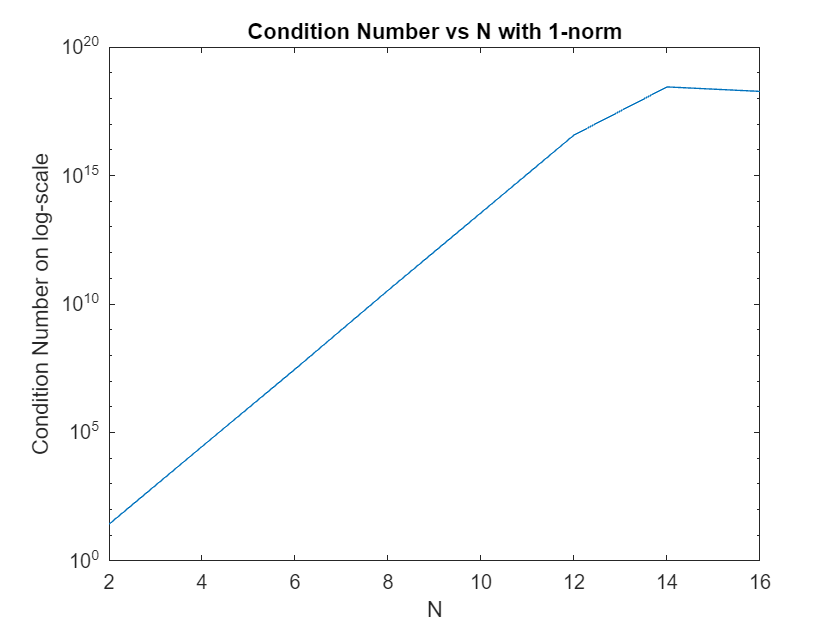

[C_1, C_2, C_inf] = deal([]);
N = 2:2:16;

for n = N
    H = hilb(n); 
    C_1 = [C_1; cond(H, 1)];
    C_2 = [C_2; cond(H, 2)];
    C_inf = [C_inf; cond(H, inf)];
end
figure();
semilogy(N, C_1);
xlabel('N');
ylabel('Condition Number on log-scale');
title('Condition Number vs N with 1-norm');

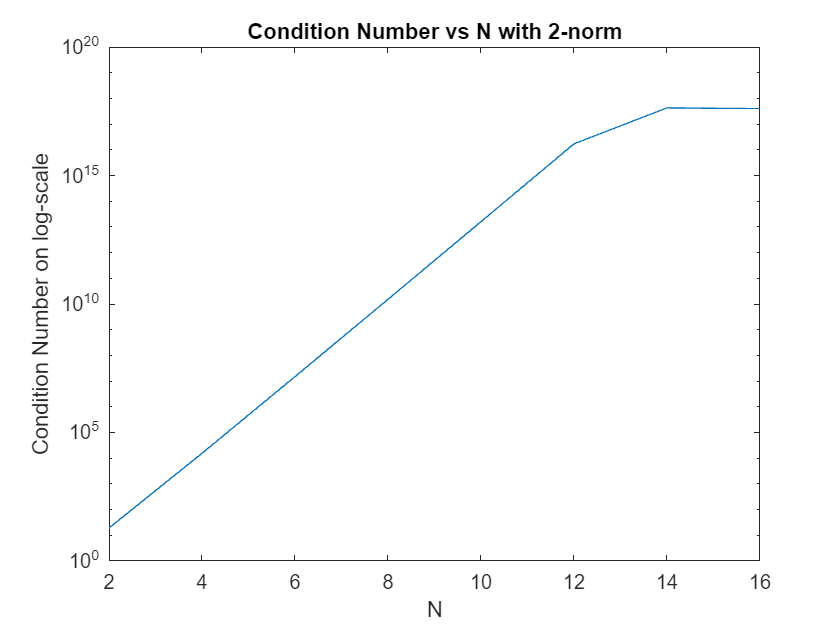

figure();
semilogy(N, C_2);
xlabel('N');
ylabel('Condition Number on log-scale');
title('Condition Number vs N with 2-norm');

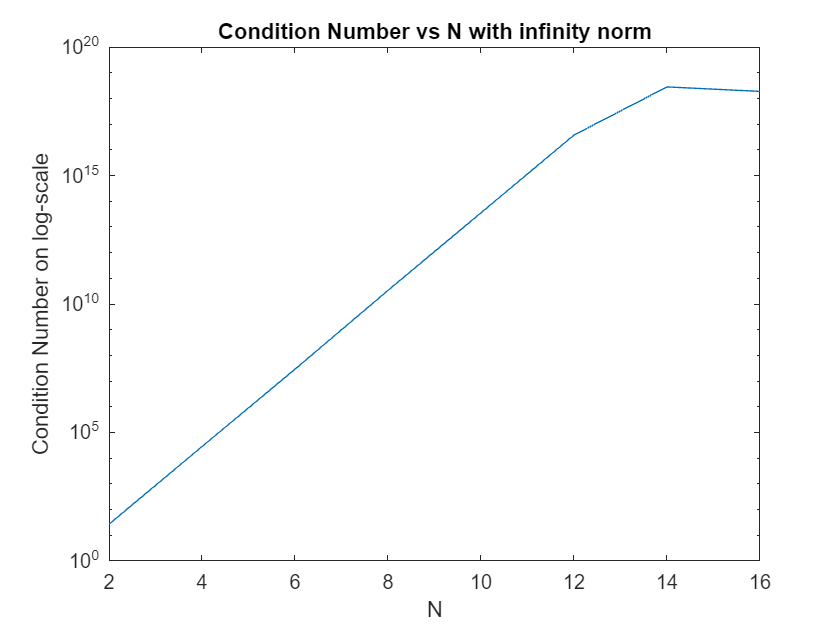

figure();
semilogy(N, C_inf);
xlabel('N');
ylabel('Condition Number on log-scale');
title('Condition Number vs N with infinity norm');

### Observations and Conjecture:

According to the above graphs, there is a linear relationship between N and log of condition number of H. This implies that the condition number of the Hilbert matrix grows exponentially with size N. Beyond 10^15 and somewhere around 10^17, the matrix becomes extremely ill-conditioned and behaves like a singular matrix numerically. Also we can observe that there is a change in the nature of curve beyond this point and linearity is somewhat lost.

## Question 3

N = 8:2:12;
    
[cond_arr, norm1, norm2, norm3] = deal([]);
for n = N
    H = hilb(n);
    HI = invhilb(n);
    x = rand(n,1);

    b = H * x;
    x1 = H \ b;
    x2 = HI*b;
    x3 = geppsolve(H, b);

    fprintf('\nFor n = %d,\n', n);
    fprintf('x = \n');
    disp(x);

    fprintf('x1 = \n');
    disp(x1);

    fprintf('x2 = \n');
    disp(x2);

    fprintf('x3 = \n');
    disp(x3);

    cond_arr = [cond_arr; cond(H)];
    norm1 = [norm1; norm(x-x1)/norm(x)];
    norm2 = [norm2; norm(x-x2)/norm(x)];
    norm3 = [norm3; norm(x-x3)/norm(x)];
end


For n = 8,


x = 


     2.501083818490608e-01
     8.379329892234851e-01
     4.380205493710055e-01
     9.416527979433841e-01
     6.603111317146847e-01
     2.660838348879369e-02
     1.362401692943578e-01
     8.974643937648631e-01



x1 = 


     2.501083818568375e-01
     8.379329888416116e-01
     4.380205540618558e-01
     9.416527736822271e-01
     6.603111947838352e-01
     2.660829670602108e-02
     1.362402296603950e-01
     8.974643770534921e-01



x2 = 


     2.501083818715415e-01
     8.379329892341048e-01
     4.380205553025007e-01
     9.416527450084686e-01
     6.603112220764160e-01
     2.660810947418213e-02
     1.362402737140656e-01
     8.974644094705582e-01



x3 = 


     2.501083818568375e-01
     8.379329888416116e-01
     4.380205540618558e-01
     9.416527736822271e-01
     6.603111947838352e-01
     2.660829670602108e-02
     1.362402296603950e-01
     8.974643770534921e-01




For n = 10,


x = 


     2.876293671046530e-01
     2.081437906974051e-01
     7.342681079110888e-01
     8.866990953365433e-01
     1.026960670694603e-01
     2.393740079800628e-01
     2.207550021240017e-01
     5.489708593518859e-01
     6.927231843790242e-01
     3.016338481439946e-01



x1 = 


     2.876293669811145e-01
     2.081437990876103e-01
     7.342679658831791e-01
     8.867001252603945e-01
     1.026921592069323e-01
     2.393824737917086e-01
     2.207442475676695e-01
     5.489786718216573e-01
     6.927202510977661e-01
     3.016342693501579e-01



x2 = 


     2.876293669105507e-01
     2.081437222659588e-01
     7.342691421508789e-01
     8.866920471191406e-01
     1.027450561523438e-01
     2.393951416015625e-01
     2.208557128906250e-01
     5.487976074218750e-01
     6.927490234375000e-01
     3.016281127929688e-01



x3 = 


     2.876293669811145e-01
     2.081437990876103e-01
     7.342679658831791e-01
     8.867001252603945e-01
     1.026921592069323e-01
     2.393824737917086e-01
     2.207442475676695e-01
     5.489786718216573e-01
     6.927202510977661e-01
     3.016342693501579e-01




For n = 12,


x = 


     2.322653415063769e-02
     9.179208287279472e-01
     5.324441441147837e-01
     6.021986755674135e-01
     8.279747877410171e-01
     9.615902038106534e-01
     8.441600989782650e-01
     4.753951196926158e-01
     6.670494339349193e-01
     1.139664289585366e-01
     5.245112036371808e-01
     7.865318654646920e-01



x1 = 


     2.322651550166338e-02
     9.179231568997450e-01
     5.323717960998908e-01
     6.031748423239347e-01
     8.208767104848578e-01
     9.925623675570682e-01
     7.583774930508391e-01
     6.298651528132023e-01
     4.867838726339188e-01
     2.454501362703256e-01
     4.700442702917983e-01
     7.963130218292007e-01



x2 = 


     2.322648558765650e-02
     9.179278612136841e-01
     5.322685241699219e-01
     6.039428710937500e-01
     8.217773437500000e-01
     1.050781250000000e+00
     6.718750000000000e-01
     6.093750000000000e-01
     2.343750000000000e-01
     4.062500000000000e-01
     4.218750000000000e-01
     8.066406250000000e-01



x3 = 


     2.322651550166338e-02
     9.179231568997450e-01
     5.323717960998908e-01
     6.031748423239347e-01
     8.208767104848578e-01
     9.925623675570682e-01
     7.583774930508391e-01
     6.298651528132023e-01
     4.867838726339188e-01
     2.454501362703256e-01
     4.700442702917983e-01
     7.963130218292007e-01



T = table(N', cond_arr, norm1, norm2, norm3);
T.Properties.VariableNames = {'n', 'cond(H)', 'norm(x-x1)/norm(x)', 'norm(x-x2)/norm(x)', 'norm(x-x3)/norm(x)'};
disp(T);

             n                    cond(H)            norm(x-x1)/norm(x)      norm(x-x2)/norm(x)      norm(x-x3)/norm(x) 
    ____________________    ____________________    ____________________    ____________________    ____________________

    8.00000000000000e+00    1.52575754899225e+10    7.18925643885138e-08    1.76992792367800e-07    7.18925643885138e-08
    1.00000000000000e+01    1.60247788043844e+13    1.05867341107976e-05    1.33908032427290e-04    1.05867341107976e-05
    1.20000000000000e+01    1.70862075556518e+16    1.25637635568322e-01    2.50868765149990e-01    1.25637635568322e-01



### Answers:

10 digits are lost in computing x1, x2 and x3 for n = 8,

13 digits are lost in computing x1, x2 and x3 for n = 10,

For n = 12, all 16 digits are lost in computing x1, x2 and x3.

Yes, the loss of accuracy agrees with the value predicted by the Rule-of-Thumb. The value of ||x – x’||/||x|| is converted to the form such that its value <= 0.5 * 10^(-p) , then x and x’ agree at least p significant digits for all entries (indices). The corresponding result is clearly shown by the tabulated results, hence there is agreement in the loss of accuracy with the value predicted by the Rule-of-Thumb.

There isn’t much of a difference between x1, x2 and x3 since for each n, the error is of the same order and the mantissa does not vary much or with any specific pattern.

## Question 4

n = 10;
H = hilb(n);
rng(41);
x = randn(n,1);
b = H*x;
xt = H \ b;
r = H * xt - b;

disp([norm(r)/norm(b) norm(x-xt)/norm(x)]);

     7.740113293069092e-17     2.417202593434655e-05



norm(r)/norm(b)

ans =      7.740113293069092e-17


norm(x-xt)/norm(x)

ans =      2.417202593434655e-05


### Observations and Conclusion:

As we can observe that a small ||r||/||b|| does not imply a small ||x – x’||/||x||. The latter is of the order 10^(-5) while the former is of the order 10^(-17). So, there is a huge difference between them and we cannot deduce that x is sufficiently close to x’ by simply looking at ||r||/||b||.

## Question 5

rng(41);

N = [32, 64];
[condition_number, error_gepp, ratio_gepp, error_qr, ratio_qr] = deal([]);

for n = N
    x = rand(n, 1);
    
    W = Wilkinson(n);
    b = W * x;

    x_gepp = geppsolve(W, b);
    
    condition_number = [condition_number; cond(W, inf)];
    error_gepp = [error_gepp; norm(x - x_gepp, inf) / norm(x, inf)];
    ratio_gepp = [ratio_gepp; norm(W * x_gepp - b, inf) / norm(b, inf)];

    [Q, R] = qr(W);
    x_qr = colbackward(R, Q' * b);
    error_qr = [error_qr; norm(x - x_qr, inf) / norm(x, inf)];
    ratio_qr = [ratio_qr; norm(W * x_qr - b, inf) / norm(b, inf)];
end

T = table(N', condition_number, error_gepp, error_qr, ratio_gepp, ratio_qr);
T.Properties.VariableNames = {'n', 'Condition Number', 'Error using GEPP', 'Error using QR', '||r||/||b|| using GEPP', '||r||/||b|| using QR'};
disp(T);

             n                Condition Number        Error using GEPP         Error using QR       ||r||/||b|| using GEPP    ||r||/||b|| using QR
    ____________________    ____________________    ____________________    ____________________    ______________________    ____________________

    3.20000000000000e+01    3.20000000000000e+01    2.17198379876610e-08    3.35808612677705e-15     2.19642017622045e-09     3.59673193664329e-16
    6.40000000000000e+01    6.40000000000018e+01    9.09870946616053e-01    1.42183658553292e-14     1.74021164211673e-01     7.85920569213569e-16



### Answers:

a) The solution using QR decomposition appears to give a lower error in the computed solution. The error using QR decomposition is of the order 10^(-15) to 10^(-14) which is very less as compared to the error using GEPP.

b) For QR decomposition method, the Rule-of-Thumb is predicting the correct answer reasonably well. Here, t = 1 for both values of n. Hence, s – t = 15, which is also demonstrated by the forward error computed using QR decomposition method.

For GEPP, the error is of the order of 10^(-9) for n = 32, which is not at all near 10^(-16) as predicted by the Rule-of-Thumb .

c) The solution using QR decomposition method has a lower value of $$$ ||r||_{\infty}/||b||_{\infty} $$$ for both n = 32 and n = 64.

d) QR decomposition method is behaving in a backward stable manner while GEPP is not backward stable as seen by the computed data and the Rule-of-Thumb analysis. So, QR decomposition method is backward stable whereas GEPP is not backward stable.

# Function Programs

## Question 1

function G = mychol(A)
    [n,~] = size(A);
    if A(1,1) <= 0
        error('Got a negative diagonal entry');
    end
    
    G = zeros(n,n);
    g11 = sqrt(A(1,1));
    G(1,1) = g11;
    
    if n == 1
        return;
    end
    b = A(1,2:n).';
    A_hat = A(2:n,2:n);
    g = G(1,2:n).';
    g = b/g11;
    G(1,2:n) = g.';
    G(2:n,2:n) = mychol(A_hat - g*g.');
    return;
end

## Question 3

This function is to be called as x = colbackward(U, b).

x = colbackward(U,b) solves an upper triangular system U x = b by column oriented back substitution.

function x = colbackward(U, b)
    [n, ~] = size(U);
    
    for i = n: -1: 1
        if U(i, i) ~= 0
            b(i) = b(i) / U(i, i);
        else
            error('Matrix is Singular');
        end
     
        for j = i - 1: -1: 1
            b(j) = b(j) - U(j, i) * b(i);
        end
    end
   
    x = b;
end

This function is to be called as x = rowforward(L, b).

x = rowforward(L,b) solves a lower triangular system L x = b by row oriented forward substitution.

function x = rowforward(L, b)
    [n, ~] = size(L);
    
    for k = 1: n
        for j = 1: k - 1
            b(k) = b(k) - L(k, j) * b(j);
        end
        
        if L(k, k) ~= 0
            b(k) = b(k) / L(k, k);
        else
            error('Matrix is Singular');
        end
    end
    
    x = b;
end

This function is to be called as [L, U, p] = gepp(A).

It finds an LU factorization A = LU of an n-by-n matrix A and a column vector p satisfying A(p, :) = LU via Gaussian Elimination with partial pivoting (GEPP).

function [L, U, p] = gepp(A)
    
    [n, ~] = size(A);
    p = (1: n);
    for k = 1: n - 1
        [~, idx] = max(abs(A(k: end, k)));
        idx = idx + k - 1;
        if idx ~= k
            permutation = [idx, k];
            A(permutation, :) = A(permutation([2, 1]), :);
            p(permutation) = p(permutation([2, 1]));
        end
        if A(k, k) ~= 0
            A(k + 1: n, k) = A(k + 1: n, k) / A(k, k);
        end
        A(k + 1: n, k + 1: n) = A(k + 1: n, k + 1: n) - A(k + 1: n, k) * A(k, k + 1: n);
    end
    L = eye(n) + tril(A, -1);
    U = triu(A);
end

This function is to be called as x = geppsolve(A, b).

It solves the system Ax = b via GEPP.

function x = geppsolve(A, b)

    [L, U, p] = gepp(A);
   
    y = rowforward(L, b(p, :));
    x = colbackward(U, y);
end

## Question 5

This function is to be called as W = Wilkinson(n).

It creates a square Wilkinson matrix without using for loops.

function W = Wilkinson(n)
    W = (tril(ones(n)) .* -1) + (eye(n) .* 2);
    W(:, end) = 1;
end